Question: 2.a)


$$\textrm{The}\;\textrm{frequency}\;\textrm{response}\;\textrm{function}\;\textrm{is},\;\;\;\;G\left(e^{j\omega } \right)=\frac{0\ldotp 072\;e^{j\omega } \;+\;0\ldotp 062}{e^{\;2j\omega } \;-\;1\ldotp 6{\;e}^{j\omega } \;+\;0\ldotp 63}$$


Gz = tf([0.072, 0.062], [1, -1.6, 0.63], 1)

Gz =
 
   0.072 z + 0.062
  ------------------
  z^2 - 1.6 z + 0.63
 
Sample time: 1 seconds
Discrete-time transfer function.



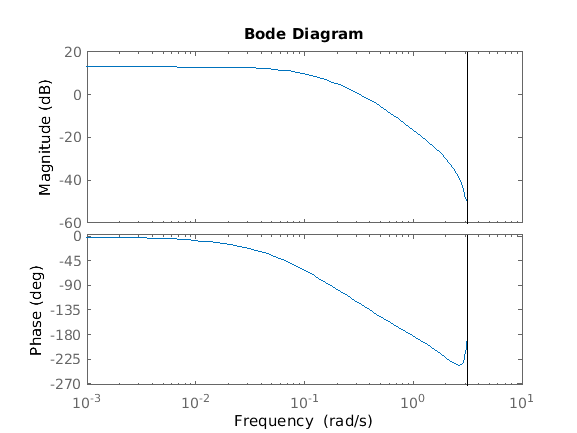

bode(Gz)

Question: 2.b)

model_polynomial = idpoly(1, [0, 0.072, 0.062], 1, 1, [1, -1.6, 0.63]);

uk_63 = idinput(63, 'prbs', [0, 1],[-1, 1]);
uk_2047 = idinput(2047, 'prbs', [0, 1],[-1, 1]);
uk_2047_coloured = idinput(2047, 'prbs', [0, 0.4],[-1, 1]);

uk_2047_sine = idinput(2047, 'sine', [0, 0.4],[-1, 1]);

ykstar_63 = sim(model_polynomial, uk_63);
ykstar_2047 = sim(model_polynomial, uk_2047);
ykstar_2047_coloured = sim(model_polynomial, uk_2047_coloured);
ykstar_2047_sine = sim(model_polynomial, uk_2047_sine);


dataset_63 = iddata(ykstar_63, uk_63, 1);
dataset_2047 = iddata(ykstar_2047, uk_2047, 1);
dataset_2047_coloured = iddata(ykstar_2047_coloured, uk_2047, 1);
dataset_2047_sine = iddata(ykstar_2047_sine, uk_2047_sine, 1);

dataset_63 = detrend(dataset_63,0);
dataset_2047 = detrend(dataset_2047,0);
dataset_2047_coloured = detrend(dataset_2047_coloured,0);
dataset_2047_sine = detrend(dataset_2047_sine,0);

G_hat_63 = etfe(dataset_63);
G_hat_2047 = etfe(dataset_2047);
G_hat_2047_coloured = etfe(dataset_2047_coloured);
G_hat_2047_sine = etfe(dataset_2047_sine);


(i) Full-length PRBS of length N = 63

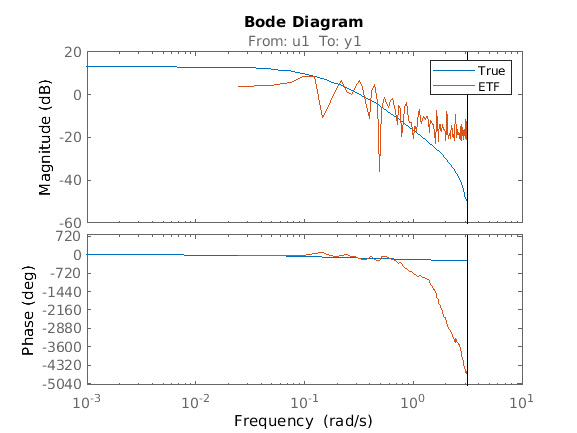

figure; bode(model_polynomial, G_hat_63);
axes_handles = findall(gcf, 'type', 'axes');
legend(axes_handles(3),'True', 'ETF');

(ii) Full-length PRBS of length N = 2047

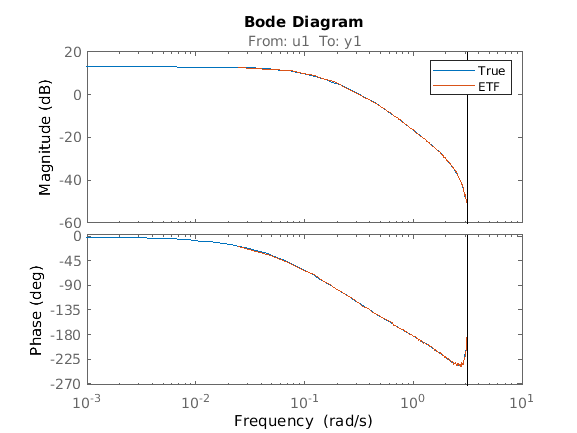

figure; bode(model_polynomial, G_hat_2047);
axes_handles = findall(gcf, 'type', 'axes');
legend(axes_handles(3),'True', 'ETF');

(iii) Coloured PRBS ( using band = [0,0.4] )

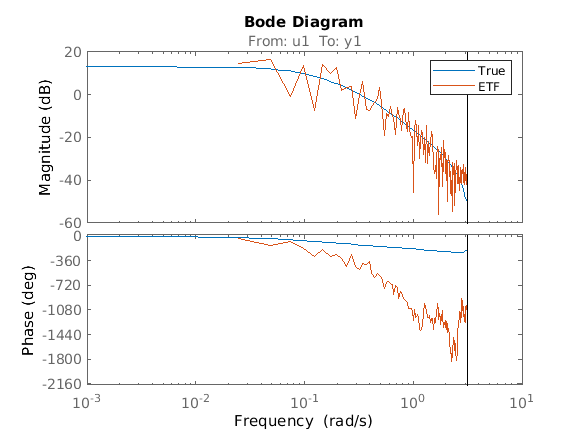

figure; bode(model_polynomial, G_hat_2047_coloured);
axes_handles = findall(gcf, 'type', 'axes');
legend(axes_handles(3),'True', 'ETF');

(iv) Mixed sine in the frequency range ω ∈ [0, 0.4]

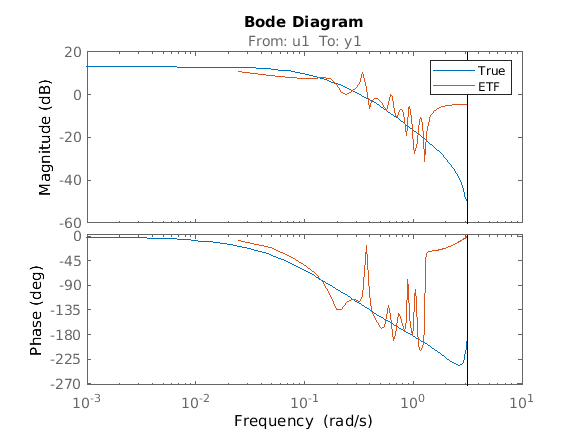

figure; bode(model_polynomial, G_hat_2047_sine);
axes_handles = findall(gcf, 'type', 'axes');
legend(axes_handles(3),'True', 'ETF');

Question: 2.c)

We know that, 

        
$${\left|\;R\right.}_N \left(\omega \right)|\;\le 2C_u \;\frac{C_G }{\sqrt{N}}$$


- Therefore for a large value of N = 2047 samples, $R_N$ is very small. As a result the estimated ETF using a full-length PRBS, $\hat{G\;} \left(e^{j\omega_n } \right)$ is nearly equal to the true FRR, $G\left(e^{j\omega_n } \right)\ldotp$ 

- When a full-length PRBS with N = 63 samples is used, we can observe that the estimated ETF is way of from the true FRF.

- For N = 2047 samples, coloured PRBS and sine-wave with a band of [0 0.4] did not a good job in estimating the true FRF when compared to a full length PRBS.